**Description:**

This FEX submission includes files for solving a linear equation in a minimum $L^1$ norm sense,

                    
$${\min}. \,\,\,\,\left|| Cx-d\right||_1$$


subject to linear and possibly integer constraints on the unknown parameter vector $x$. When there are no integer constraints, one can use `minL1lin`, whose syntax,

`        [x,resnorm,residual,exitflag,output,lambda] =  minL1lin(C,d,A,b,Aeq,beq,lb,ub,x0,options)`

is the same as for  `lsqlin` with all the same defaults for `A,b,..,x0`. However, the "options" are those of `linprog` which is used by the algorithm internally. When integer constraints are present, one may use `minL1lintin`, whose syntax is,

`        [x,resnorm,residual,exitflag,output,lambda] =  minL1intlin(C,d,intcon,A,b,Aeq,beq,lb,ub,x0,options)`

This routine is very similar except that `intlinprog` is the solver that is used internally. The arguments `intcon,A,b,Aeq,beq,lb,ub,x0,options` are all as for `intlinprog`. Some examples of these routines are given below.

**Example 1: Constrained and Unconstrained Equation Solving**

We first construct some equation data,

         
         C=rand(30,3);
         xtrue=(1:3).';
         d=C*xtrue;

and add some corrupting noise to `d`,

         
         dnoisy=d+rand(30,1)*.6; %noise corrupted version of dTrue

First, we will calculate the unconstrained minimum $L^1$ norm solution of $\mathrm{Cx}=\mathrm{dnoisy}$,

         [xUnc, resUnc] = minL1lin(C,dnoisy,[],[],[],[],[],[],[],optimset('Display','none'));

Additionally, we calculate a constrained solution based on additional properties that we'll assume are *a priori* known about `xtrue`,

                Aeq=[1,1,1];
                beq=6;
                lb=[1;1;1];
                ub=[3;3;3];

                options=optimoptions(@linprog,'Algorithm','dual-simplex','Display','none');


           [xCon,resCon] = minL1lin(C,dnoisy,[],[],Aeq,beq,lb,ub,[],options);

To verify the optimality of the unconstrained solution `xUnc,` we evaluate the objective function at numerous random points in its near neighborhood.

         xNeighbors = xUnc + randn(3,1e4)*1e-6; 
         
         errNeighbors=sum(abs(  C*xNeighbors-dnoisy )); %L1 error of neighbors

Histograms of the residual errors show that the `minL1lin` did reach a value generally more optimal than its neighbors

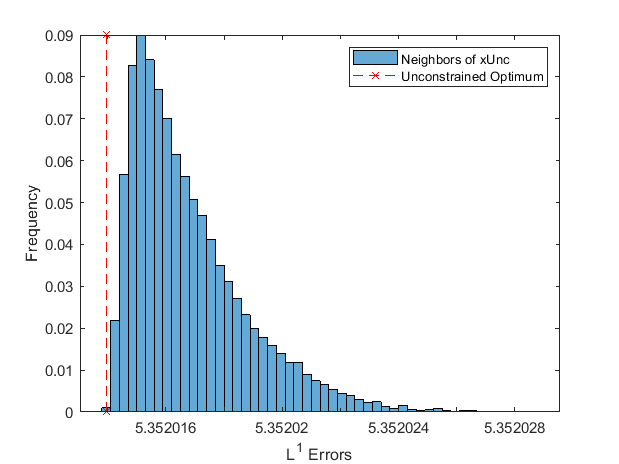

         
         histogram(errNeighbors,'Normalization','probability');
         hold on
         plot([resUnc,resUnc],ylim,'rx--')
         hold off
         xlabel 'L^1 Errors'
         ylabel 'Frequency'
         legend('Neighbors of xUnc','Unconstrained Optimum')

Additionally, we can assess the benefit of adding the constraints by looking at the error of each solution relative to the true, non-noisy value of `d`. As expected, the constrained solution has smaller error:

errorUnc = norm(C*xUnc-d,1),

errorUnc = 9.7699


errorCon = norm(C*xCon-d,1),

errorCon = 1.0994

**Example 2: Optimal Reordering of Points**

In this example, we demonstrate the application of `minL1intlin` to finding the permutation matrix that best sorts a set of 2D points into agreement with a set of similar points. As input data, we have the following clouds of 2D point coordinates, given as columns of the matrices `A` and `B`:

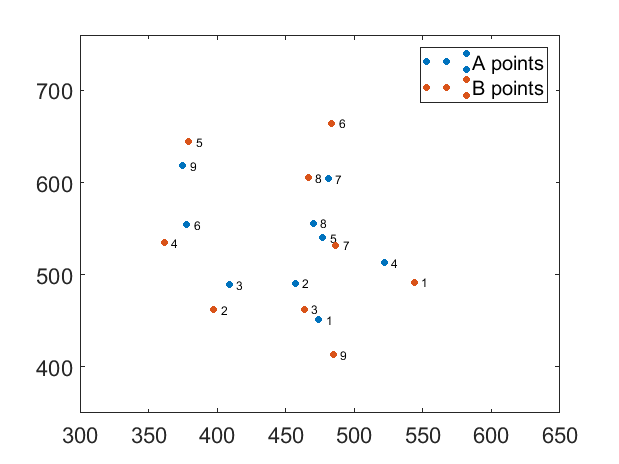

A=[474   457   409   522   477   378   481   470   375
   451   491   489   513   540   554   604   556   618];

B=[543.6821  397.4267  463.5393  361.6006  379.1301  483.5645  486.3373  466.3921  484.5759
   491.9389  461.8762  462.5541  534.5929  644.4602  664.2503  531.7277  605.1583  413.3822];

N=size(A,2);
plot(graph(1:N,1:N),'EdgeColor','none','XData',A(1,:),'YData',A(2,:));
hold on
plot(graph(1:N,1:N),'EdgeColor','none','XData',B(1,:),'YData',B(2,:));
hold off
legend('A points','B points')
set(gca,'FontSize',15)
axis([300,650,350,760])

The goal now is to re-order the columns of A to maximize the proximity of each point to a corresponding point in `B`. Mathematically, this can be posed as,

            
$${\rm min}. \,\,\, \sum_{j=1}^N \left||AP(:,j)-B(:,j)\right||_1$$


where `P` is constrained to be an `NxN` permutation matrix. In other words, it should satisfy,

            
$$\,\,\,\,\,\,P(i,j)\in\{0,1\}\\
\sum_{i=1}^N P(i,j)=1,\,\,\,\,\,\, \forall j=1,\ldots,N\\
\sum_{j=1}^N P(i,j)=1,\,\,\,\,\,\, \forall i=1,\ldots,N\\$$


We can apply `minL1intlin` to the solution of this problem as below,

    e=ones(1,N);
    P=nan(N);
    E=speye(N);

    intcon=1:N^2;    %binary, integer constraints
    lb=zeros(1,N^2);  
    ub=ones(1,N^2);
        
    Aeq=[ kron(E,e) ; kron(e,E) ]; %row/column sum constraints
    beq=[e,e].';
    
    C=kron(E,A);    %equation data
    d=B(:);
    
    opts=optimoptions(@intlinprog, 'Display','none');

    P(:)=minL1intlin(C,d,intcon,[],[],Aeq,beq,lb,ub,[],opts);

Finally, we use the optimized permutation matrix P to re-order the data and plot the result. Clearly the ordering of the points now shows much better correspondence.

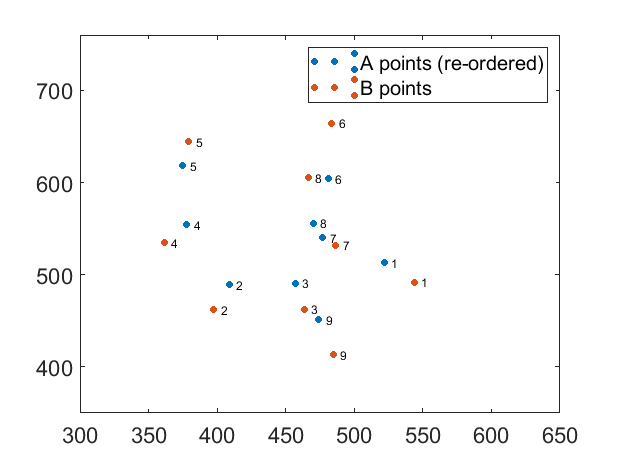

    AP=A*P; %re-order A
    
    plot(graph(1:N,1:N),'EdgeColor','none','XData',AP(1,:),'YData',AP(2,:));
    hold on
    plot(graph(1:N,1:N),'EdgeColor','none','XData',B(1,:),'YData',B(2,:));
    hold off
    legend('A points (re-ordered)','B points')
    set(gca,'FontSize',15)
    axis([300,650,350,760])